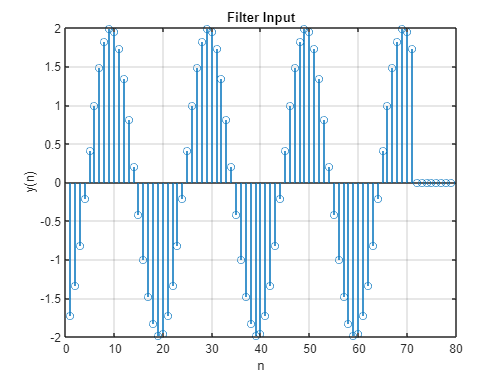

clc
clear all

%----------Question 1-------------%

% 8 point MA filter
h = (ones(1,8))./8;

% Overshooting of n to 70 samples instead of 40
n = 0:1:70;

% input
x = 2 * (sin((pi*n / 10) - (pi / 3)));

% Create a matrix and fill it with zeros
N1 = length(x);
N2 = length(h);
x = [x,zeros(1,N2)];
h = [h,zeros(1,N1)];

% Moving Average filter output
for i = 1: N1 + N2 - 1
    y(i) = 0;
    for j = 1:N1
        if((i-j+1)>0)
        y(i)=y(i)+(x(j)*h(i-j+1));
        end
    end
end

n = 0:1:length(y)-1;

% Plot of Filter input
stem(x);
grid;
xlabel('n');
ylabel('y(n)')
title('Filter Input')

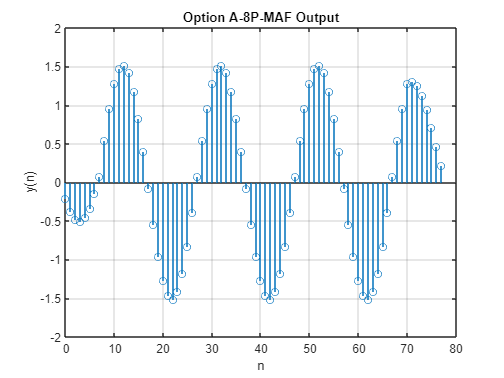


% Plot of Output Response
stem(n,y);
grid;
xlabel('n');
ylabel('y(n)')
title('Option A-8P-MAF Output')

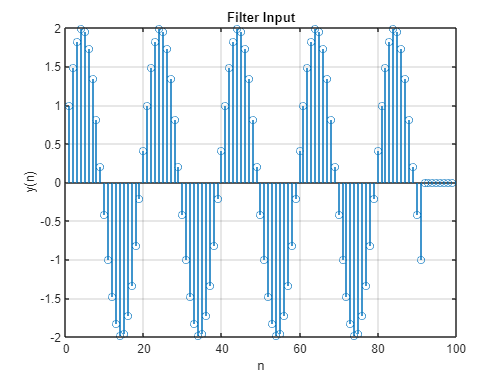




%-------------------OPTION B-----------------%
h = (ones(1,8))./8;

% Overshooting of n to 90 samples instead of 60
n = 0:1:90;

% input
x = 2 * (cos((pi*n / 10) - (pi / 3)));

% Create a matrix and fill it with zeros
N1 = length(x);
N2 = length(h);
x = [x,zeros(1,N2)];
h = [h,zeros(1,N1)];

% Moving Average filter output
for i = 1: N1 + N2 - 1
    y(i)=0;
    for j = 1:N1
        if((i-j+1)>0)
        y(i)=y(i)+(x(j)*h(i-j+1));
        end
    end
end

n=0:1:length(y)-1;

% Plot of Filter input
stem(x);
grid;
xlabel('n');
ylabel('y(n)')
title('Filter Input')

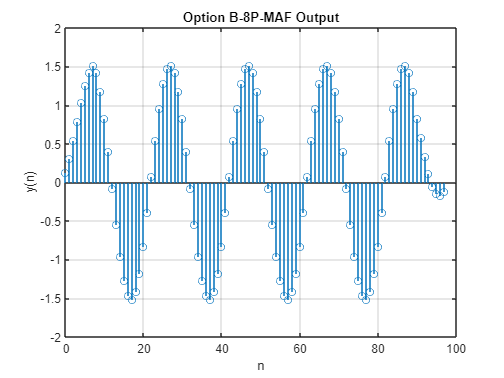


% Plot of Output Response
stem(n,y);
grid;
xlabel('n');
ylabel('y(n)')
title('Option B-8P-MAF Output')

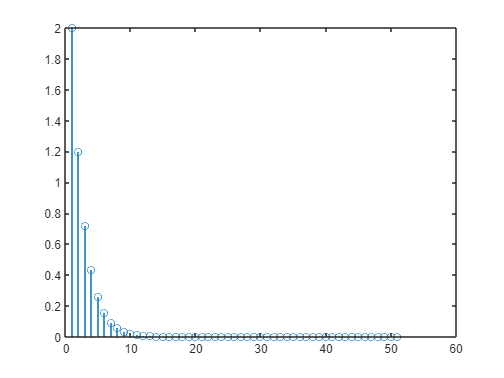


%----------Question 2-------------%

%-----------------OPTION A-----------------%
% Index
n = 0:50; 
% Unit step signal
u = (n >= 0); 
% h[n] 
h = 2*0.6.^n.*u; 

% A
x1 = u; 
% Output to Response A
a_y = conv(h,x1); 

% B
x2 = cos(n*pi/4).*u; 
% Output to Response B
b_y = conv(h,x2);

% C
x3 = u + cos(n*pi/4).*u; 
% Output To Response C
c_y = conv(h,x3); 

% Plot of h[n] 
stem(h)

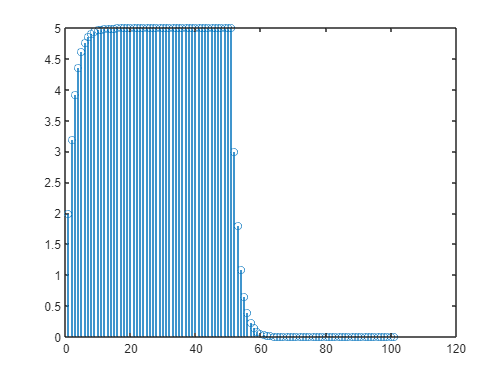

%------------Response Plot-------------%
% Plot of response A
stem(a_y)

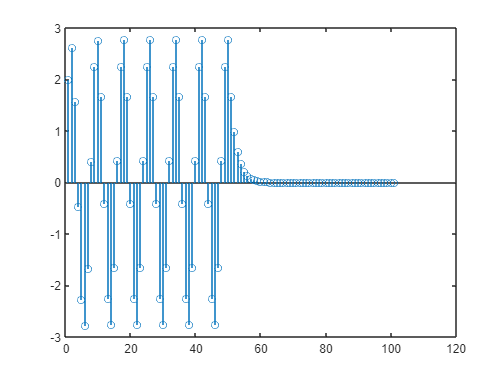

% Plot of response B
stem(b_y) 

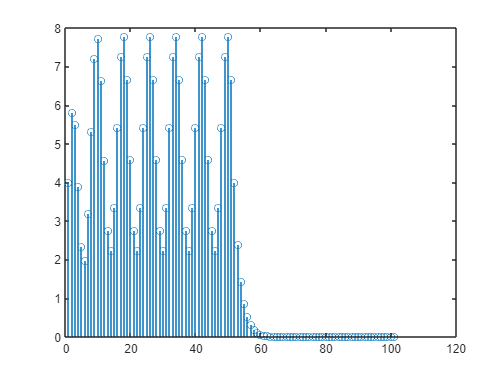

% Plot of response C
stem(c_y) 

% Plot of response a+b=c satisfies linearity check
stem(a_y + b_y)


Result = 'From Observing the Plots you can realise that the response of c_y is the same as response of  a_y + b_y hence system is linear';
disp(Result)

From Observing the Plots you can realise that the response of c_y is the same as response of  a_y + b_y hence system is linear


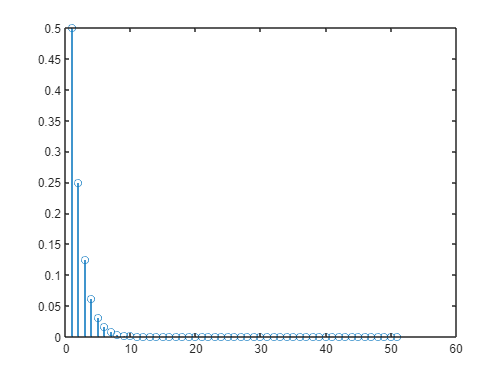



%-----------------OPTION B-----------------%
% Index
n = 0:50; 
% Unit step signal
u = (n >= 0); 
% h[n] 
h = 0.5.^(n + 1).*u; 

% A
x1 = u; 
% Output to Response A
a_y = conv(h,x1); 

% B
x2 = cos(n*pi/4).*u; 
% Output to Response B
b_y = conv(h,x2);

% C
x3 = u + cos(n*pi/4).*u; 
% Output To Response C
c_y = conv(h,x3); 

% Plot of h[n] 
stem(h)

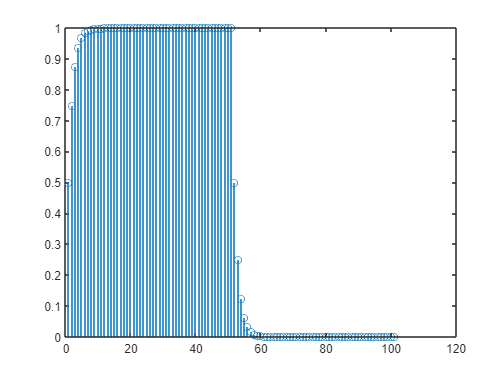

%------------Response Plot-------------%
% Plot of response A
stem(a_y)

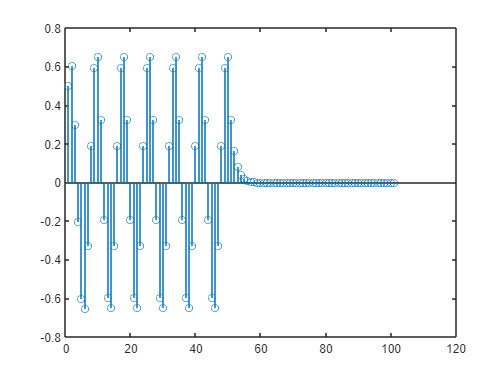

% Plot of response B
stem(b_y) 

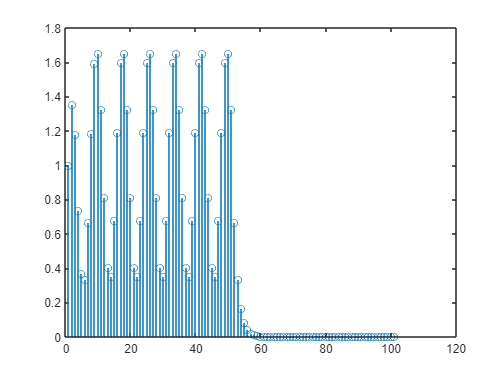

% Plot of response C
stem(c_y) 

% Plot of response a+b=c satisfies linearity check
stem(a_y + b_y)


Result = 'From Observing the Plots you can realise that the response of c_y is the same as response of  a_y + b_y hence system is linear';
disp(Result)

From Observing the Plots you can realise that the response of c_y is the same as response of  a_y + b_y hence system is linear




%----------Question 3-------------%

% A - initial conditions (y(0) = 1. y'(0) = 2
% Initialise sampling frequency and range of values
T = 0.02;
n = 0:T:20;

% Iniitalise required arguments for recur
a = [(-2 + T) (-T + 4*T.^2 + 1)];
b = [0 0 0];
x = ones(1, length(n));
x0 = [0 0];
y0 = [1 2.*T + 1];

% Get values and plot results
y = recur(a, b, n, x, x0, y0);

x =      0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


a1 =     0.9816   -1.9800


b1 =      0     0     0


y =     1.0776    1.1128    1.1455    1.1759    1.2037    1.2292    1.2522    1.2728    1.2909    1.3067    1.3201    1.3311    1.3398    1.3462    1.3503    1.3522    1.3519    1.3494    1.3448    1.3382    1.3295    1.3189    1.3063    1.2919    1.2757    1.2577    1.2381    1.2168    1.1940    1.1697    1.1440    1.1169    1.0885    1.0589    1.0282    0.9963    0.9635    0.9297    0.8951    0.8597    0.8235    0.7867    0.7493    0.7114    0.6731    0.6344    0.5953    0.5561    0.5167    0.4772


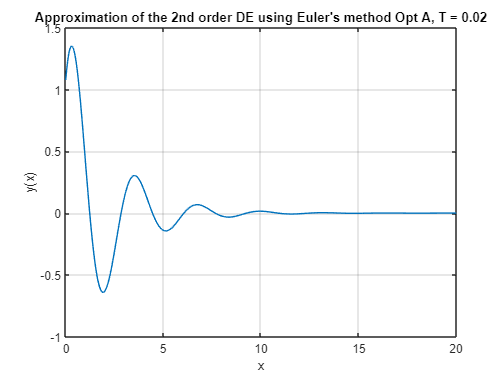


figure
plot(n, y)
grid
xlabel("x")
ylabel("y(x)")
title("Approximation of the 2nd order DE using Euler's method Opt A, T = 0.02")


% B - only initial conditions change. but both options still have the same
% y(0) = -2, y'(0) = -1

% Initialise sampling frequency and range of values
T = 0.02;
n = 0:T:20;

% Initialise required arguments for recur
a = [(-2 + T) (-T + 4*T.^2 + 1)];
b = [0 0 0];
x = ones(1, length(n));
x0 = [0 0];
y0 = [-2 -T-2];

% Get values and plot
y = recur(a, b, n, x, x0, y0);

x =      0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


a1 =     0.9816   -1.9800


b1 =      0     0     0


y =    -2.0364   -2.0492   -2.0586   -2.0644   -2.0669   -2.0660   -2.0618   -2.0544   -2.0438   -2.0302   -2.0135   -1.9940   -1.9716   -1.9465   -1.9187   -1.8883   -1.8555   -1.8204   -1.7829   -1.7434   -1.7017   -1.6581   -1.6126   -1.5654   -1.5166   -1.4662   -1.4144   -1.3613   -1.3070   -1.2516   -1.1952   -1.1380   -1.0800   -1.0213   -0.9621   -0.9024   -0.8424   -0.7821   -0.7217   -0.6612   -0.6008   -0.5406   -0.4805   -0.4209   -0.3616   -0.3029   -0.2447   -0.1873   -0.1306   -0.0747


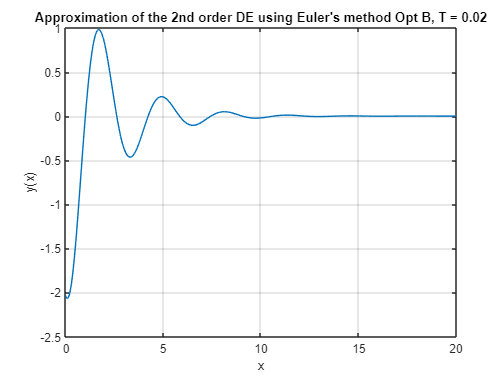


figure
plot(n, y)
xlabel("x")
ylabel("y(x)")
title("Approximation of the 2nd order DE using Euler's method Opt B, T = 0.02")
grid


%----------Question 4-------------%

%---------Part A---------%
clear;

plotTo = 20;
syms t tau;

h = exp(-t)*sin(t);
IsA = (1-cos(t))*(heaviside(t)-heaviside(t-plotTo));
IsB = (1+sin(t))*(heaviside(t)-heaviside(t-plotTo)); 

% the calculation for the terms inside each integral is performed here
toIntegrateA = subs(h,tau)*subs(IsA,t-tau);
toIntegrateB = subs(h,tau)*subs(IsB,t-tau);

% the integrations for each convolution are calculated and printed to display
IoA = int(toIntegrateA,tau,0,t)

$$IoA = \begin{array}{l} \mathrm{heaviside}\left(t-20\right)\,\left(\frac{\cos\left(t\right)}{5}+\sigma_{1}-\frac{{\mathrm{e}}^{20-t}\,\left(2\,\cos\left(t-40\right)+\sin\left(t-40\right)+5\,\sin\left(t\right)\right)}{10}+\frac{{\mathrm{e}}^{20-t}\,\left(\cos\left(t-20\right)+\sin\left(t-20\right)\right)}{2}-\frac{1}{2}\right)-\mathrm{heaviside}\left(t\right)\,\left(\frac{\cos\left(t\right)}{5}+\sigma_{1}+\frac{3\,{\mathrm{e}}^{-t}\,\cos\left(t\right)}{10}-\frac{{\mathrm{e}}^{-t}\,\sin\left(t\right)}{10}-\frac{1}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sin\left(t\right)}{5} \end{array}$$

IoB = int(toIntegrateB,tau,0,t)

$$IoB = \begin{array}{l} -\mathrm{heaviside}\left(t\right)\,\left(\sigma_{1}-\frac{\sin\left(t\right)}{5}+\frac{{\mathrm{e}}^{-t}\,\cos\left(t\right)}{10}+\frac{3\,{\mathrm{e}}^{-t}\,\sin\left(t\right)}{10}-\frac{1}{2}\right)-\mathrm{heaviside}\left(t-20\right)\,\left(\frac{\sin\left(t\right)}{5}-\sigma_{1}+\frac{{\mathrm{e}}^{20-t}\,\left(2\,\sin\left(t-40\right)-\cos\left(t-40\right)+5\,\cos\left(t\right)\right)}{10}-\frac{{\mathrm{e}}^{20-t}\,\left(\cos\left(t-20\right)+\sin\left(t-20\right)\right)}{2}+\frac{1}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\cos\left(t\right)}{5} \end{array}$$

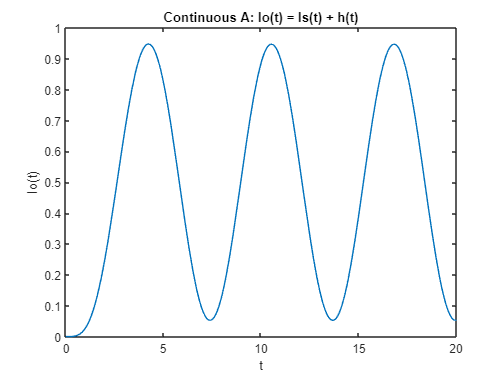


% plot for option A
fplot(t, IoA, [0 plotTo]); 
title('Continuous A: Io(t) = Is(t) + h(t)');
ylabel('Io(t)');
xlabel('t')
ylim([0 1])

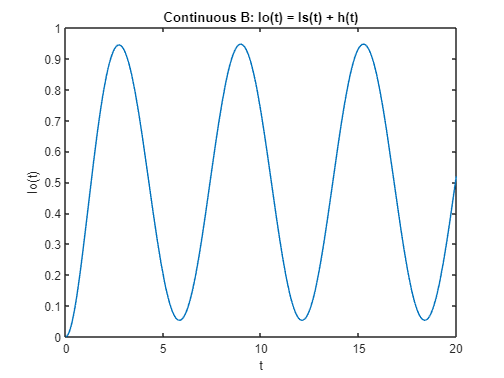


% plot for option B
fplot(t, IoB, [0 plotTo]);
title('Continuous B: Io(t) = Is(t) + h(t)');
ylabel('Io(t)');
xlabel('t')
ylim([0 1])

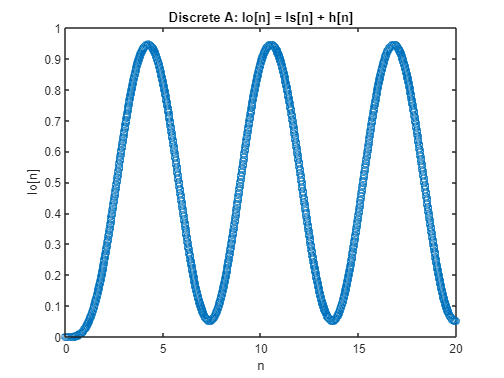


%-----------Part B----------%

plotTo = 20; % value the convolution will occur to 
T = 0.01; % sample rate
n = 0:T:plotTo; % discrete values to convolute over

% definitions for h and the Is values of part A and B
h = exp(-n).*sin(n);
IsA = (1-cos(n));
IsB = (1+sin(n));

% performing convolutions and scaling for parts A and B
IoA = conv(h, IsA).*T;
IoB = conv(h, IsB).*T;

% chopping of convolutions to correct dimension
IoA = IoA(1:length(n));
IoB = IoB(1:length(n));

% displaying the graphs for the discrete results
stem(n, IoA, 'linestyle','none'); 
ylim([0 1]); 
title('Discrete A: Io[n] = Is[n] + h[n]');
ylabel('Io[n]');
xlabel('n');

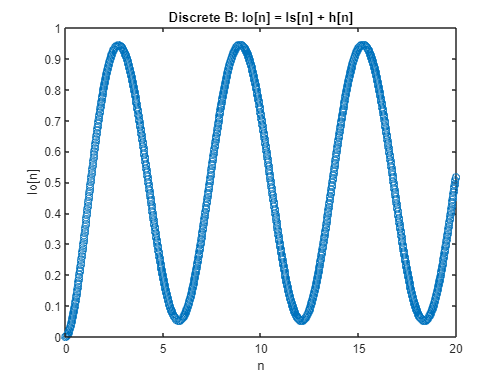


stem(n, IoB, 'linestyle','none'); 
ylim([0 1]); 
title('Discrete B: Io[n] = Is[n] + h[n]');
ylabel('Io[n]');
xlabel('n');


%---------Part C---------%

%Looking at the plots for both the continuous and discrete-time methods reveals that these plots look identical to
%each other when viewed at this scale. This is because the small sample rate of 0.01 for the discrete convolution
%forms an excellent approximation of the solution for the continuous version.
